%----------------
%Homework 2
%----------------

%Date: 2/21/25

%Problem 4

clear;
close all;


% Square Root Approximation: x = (x+(a/x)) /2

iter = 10; %Number of Iterations

num = 5; % Number we're taking sqrt of 

sol = 9; %Initial Guess

%Initilizing Array for Solution Results
sol_results = zeros(1,iter);
sol_results(1) = sol;

n = 2; % Significant Figures

es = (0.5*10^(2-n)) % Stopping Criteria

es = 0.5000


for i=1:iter
    sol_old = sol;
    
    sol = (sol_old + (num/sol_old))/2;
    if sol ~= 0
        sol_results(i) = sol; 
        ea = abs((sol-sol_old)/sol) * 100;
        if ea <= es
            count = (i)
            break
        end
    end
end

count = 5

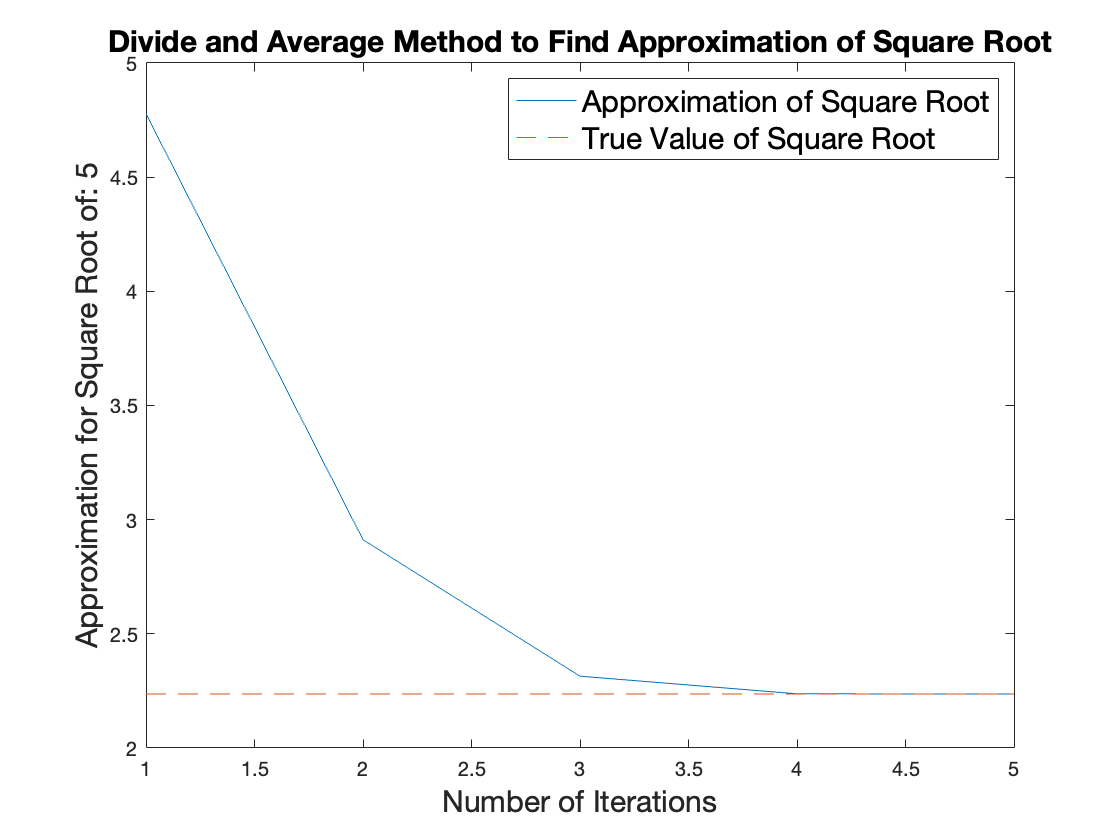


sol_results = sol_results(1:count); %Adjusting array based on number of iterative calculations


plot(linspace(1,count,count),sol_results)
xlabel('Number of Iterations','FontSize',15)
ylabel(sprintf('Approximation for Square Root of: %d', (num)), 'FontSize',15)
title("Divide and Average Method to Find Approximation of Square Root",'FontSize',15)

hold on
plot(linspace(1,count,count),ones(1,count)*sqrt(num),'--')
legend("Approximation of Square Root", "True Value of Square Root",'FontSize',15)
hold off